# Fama-MacBeth regressions and CCAPM

## Introduction

The aim of this Live Script is to illustrate the workings of standard Fama-MacBeth two-pass cross-sectional regressions, using the context of the consumption-based asset pricing framework. The script is an extension of the one used in the course Asset Pricing and elements could be familiar. In those cases, it is meant as a recap. 

I have provided you with a function fFamaMacBeth_standard() that is used to estimate a linearized consumption-based asset pricing model using the Fama-MacBeth two-pass cross-sectional regression methodology. I encourage you to go through it and understand how it relates to the formulas in the lecture slides. 

## Loading Kenneth French data

Go to Kenneth French data library ([http://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](http://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)) and download data on 25 portfolios sorted on size (ME) and book-to-market equity (BE/ME) ratios (also known as 25 size-value portfolios) and data on the risk-free rate and the excess market return, which you can find under the Fama-French 3-factor data. I have already gathered data into a .mat file and load it here.

% Housekeeping 
clear 
clc

% Loading data from mat files
load('sizeValuePortfolios.mat');
load('famaFrenchFactors.mat');

## Loading consumption-data 

Go to the St. Louis Fred database ([https://fred.stlouisfed.org/series/PCENDC96](https://fred.stlouisfed.org/series/PCENDC96)) and download data on monthly consumption. For the sake of illustration we use monthly data on (an index of) nondurables only. But be aware that monthly *consumption* data has many issues and should generally be avoided. I have already computed (logarithmic) growth rates. 

% Loading data from mat file
load('logConsGrowth.mat');

## Adapting and setting up data

In our case, we are only interested in the 1959:02 - 2018:07 sample period, which the sample already is adapted to. Note that we start from the 2nd column as the first colums contains the dates.

% Adapting to the sample size
sizeValuePortfolios     = sizeValuePortfolios(:,2:end);
SMB                     = famaFrenchFactors(:,3);
HML                     = famaFrenchFactors(:,4);
logConsGrowth           = logConsGrowth(:,2);

The matrix *famaFrenchFactors* contains a date series, the excess reeturn on the market portfolio, the factors SMB and HML, and the risk-free rate. We pick out the risk-free rate, as we will need it to compute excess returns below.

% Picking out the risk-free rate
riskFreeRate            = famaFrenchFactors(:,end);

In our formulation of the linearized CCAPM, we work with excess portfolio return. That is, we aim to estimate the following equation


$$\mathbb{E}\left[R_{it} - R_{ft}\right]= \gamma_{0}  + \gamma_{c} \beta_{ic} $$


We therefore need to compute the excess return on each of the 25 size-value portfolios, which we can do as below using the repmat() function (build in).  

% Computing excess returns for the 25 portfolios
excessPortfolioReturns  = sizeValuePortfolios - repmat(riskFreeRate,1,25);

## Descriptive statistics for the 25 size-value portfolios

We can use the following snippet of code to compute annualized mean excess returns on the portfolios along with their time series CCAPM betas. We estimate time series betas using the regression 


$$R_{it} - R_{ft}= \alpha_{i} + \beta_{ic}\tilde{c}_t + \varepsilon_{it}$$


One can note that this can be accomplished in a simple manner using Matlab by way of the backslash  (\) operator as shown below. This line essentially estimates the above regression for all *N* assets at once. However, this is only useful when we are only interested in the parameter values, but not if we are interested in inference as well. 

% Computing annualized mean excess returns
meanExcessReturns   = mean(excessPortfolioReturns).*12;

% Computing time series betas for the portfolios
iota                = ones(size(logConsGrowth,1),1);
ccapmBetas          = [iota logConsGrowth]\excessPortfolioReturns;

% Reshaping output for easier interpretability
meanExcessReturns   = reshape(meanExcessReturns,5,5)';
ccapmBetas          = reshape(ccapmBetas(2,:),5,5)';

% Display the results
meanExcessReturns

meanExcessReturns =     3.6254    9.3311    9.1824   12.0293   12.9909
    5.8897    9.1540   10.2759   11.0539   11.7577
    6.1807    9.6075    8.7262   10.5308   11.6310
    7.3659    7.5504    8.5914   10.1467    9.7425
    6.0971    6.3107    7.0251    5.8474    8.1998


ccapmBetas

ccapmBetas =     3.2104    3.1909    2.5267    2.5660    2.6197
    3.1469    2.7417    2.3338    2.3285    2.7125
    2.9142    2.8519    2.1507    2.2877    2.1749
    2.6801    2.0154    2.3042    2.2993    2.5118
    1.6491    1.5525    1.2758    1.6895    1.2550


## Estimating cross-sectional risk prices

To obtain Fama-MacBeth results, we run $T$ cross-sectional regressions


$$R_{it} - R_{ft}= \gamma_{0t}+ \gamma_{ct} \widehat{\beta}_{ic} + \eta_{it}$$


where we can use the provided function fFamaMacBeth_standard() to estimate the model. We now refer to the function as "standard", since we will see several extensions to this original approach later in the course that deals with, e.g., issues with errors-in-variables.

% Estimate the CCAPM using 25 size-value portfolios as test assets
[firstStageRes,secondStageRes]    = fFamaMacBeth_standard(excessPortfolioReturns,logConsGrowth,'true',12)

firstStageRes = struct with fields:
     beta: [2×25 double]
    tstat: [2×25 double]
       r2: [25×1 double]
    r2adj: [25×1 double]


secondStageRes = struct with fields:
      gamma: [0.6358 0.0397]
    tstatFM: [3.1017 0.3989]
         r2: 1.2756
        fit: [25×1 double]
       mean: [25×1 double]
       MAPE: 0.1502
       RMSE: 0.1891


Please read the function and understand its content. We can get it to spit out the output we need as follows

% Getting risk prices, standard errors, and t-stats
secondStageRes.gamma

ans =     0.6358    0.0397


secondStageRes.tstatFM

ans =     3.1017    0.3989


secondStageRes.r2

ans = 1.2756

## Making the pricing error plot

We can build the pricing error plot using the following snippet of code

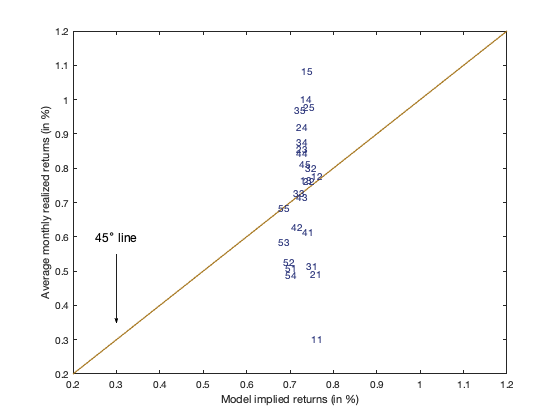

figure;
axis([0.2 1.2 0.2 1.2]);
ref = refline(1,0);
ref.Color = [166/255 118/255 29/255];
ref.LineWidth = 1.2;
xlabel('Model implied returns (in %)');
ylabel('Average monthly realized returns (in %)');
box on
labels = {'11','12','13','14','15','21','22','23','24','25',...
'31','32','33','34','35','41','42','43','44','45','51','52','53','54','55'};
hold on
text(secondStageRes.fit,secondStageRes.mean, labels,'HorizontalAlignment','center','FontSize',10,'Color',[42/255 52/255 122/255]);
text(0.3,0.6,'45\circ line','HorizontalAlignment','center','FontSize',12);
quiver(0.3,0.55,0,-0.20,0,'Color','k');
hold off

## Adding Fama-French factors

If the CCAPM was, indeed, the right model, one should expect the risk price of additional risk factors to come out insignificantly when added to the model. Our results above already hint at CCAPM not functioning very well, however for the sake of examplifying, let us add the two Fama-French factors (SMB and HML) to the model and test whether they enter significantly. 

The first-stage is altered to 


$$R_{it} - R_{ft}= \alpha_{i} + \beta_{ic}\tilde{c}_t + \beta_{iSMB}SMB_t + \beta_{iHML}HML_t + \varepsilon_{it}$$
 

and the second-stage to 

$R_{it} - R_{ft}= \gamma_{0t}+ \gamma_{ct} \widehat{\beta}_{ic} + \gamma_{SMBt}\widehat{\beta}_{iSMB} + \gamma_{HMLt}\widehat{\beta}_{iHML}+  \eta_{it}$.

Note that another way could be to include average characteristics of the firms, $\overline{BM}_i$ and $\overline{ME}_i$, only in the second stage. 

We obtain the following results. 

% Estimate the CCAPM using 25 size-value portfolios as test assets
[firstStageResFF,secondStageResFF]    = fFamaMacBeth_standard(excessPortfolioReturns,[logConsGrowth SMB HML],'true',12)

firstStageResFF = struct with fields:
     beta: [4×25 double]
    tstat: [4×25 double]
       r2: [25×1 double]
    r2adj: [25×1 double]


secondStageResFF = struct with fields:
      gamma: [0.4854 0.0855 0.1618 0.3616]
    tstatFM: [3.0563 1.1325 1.4196 3.4164]
         r2: 64.7798
        fit: [25×1 double]
       mean: [25×1 double]
       MAPE: 0.0789
       RMSE: 0.1129


% Getting risk prices, standard errors, and t-stats
secondStageResFF.gamma

ans =     0.4854    0.0855    0.1618    0.3616


secondStageResFF.tstatFM

ans =     3.0563    1.1325    1.4196    3.4164


secondStageResFF.r2

ans = 64.7798

We can build the pricing error plot to see any improvements visually.

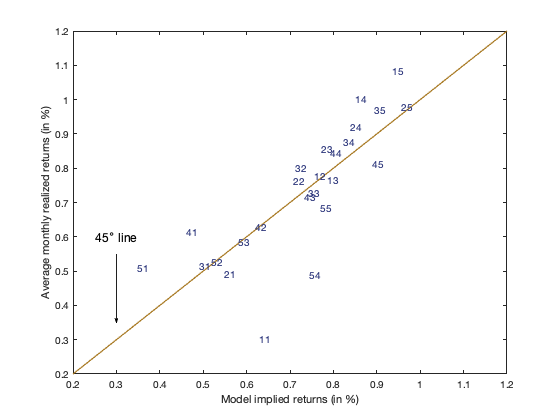

figure;
axis([0.2 1.2 0.2 1.2]);
ref = refline(1,0);
ref.Color = [166/255 118/255 29/255];
ref.LineWidth = 1.2;
xlabel('Model implied returns (in %)');
ylabel('Average monthly realized returns (in %)');
box on
labels = {'11','12','13','14','15','21','22','23','24','25',...
'31','32','33','34','35','41','42','43','44','45','51','52','53','54','55'};
hold on
text(secondStageResFF.fit,secondStageResFF.mean, labels,'HorizontalAlignment','center','FontSize',10,'Color',[42/255 52/255 122/255]);
text(0.3,0.6,'45\circ line','HorizontalAlignment','center','FontSize',12);
quiver(0.3,0.55,0,-0.20,0,'Color','k');
hold off

## Adding characteristics to the second-stage regressions

Note that another way could be to include average characteristics of the firms, $\overline{BM}_i$ and $\overline{ME}_i$, only in the second stage as per

$R_{it} - R_{ft}= \gamma_{0t}+ \gamma_{ct} \widehat{\beta}_{ic} + \gamma_{MEt}\overline{ME}_{i} + \gamma_{BMt}\overline{BM}_i+  \eta_{it}$.

Data on individiual firm characteristics can be obtained from Compustat via WRDS. Kenneth French provides few characteristics on their already sorted portfolios, which is where the following data on book-to-market ratios and size (market equity) are obtained. Note that characteristics may also enter in logarithms, see e.g. Julliard and Parker (2005) for a discussion.

% Load characteristics
load('ME.mat')
load('BM.mat')

% Collect in cell as input to function 
char = {ME,BM};

% Estimate the CCAPM using 25 size-value portfolios as test assets
[firstStageResChar,secondStageResChar]    = fFamaMacBeth_standard(excessPortfolioReturns,logConsGrowth,'true',12,char)

firstStageResChar = struct with fields:
     beta: [2×25 double]
    tstat: [2×25 double]
       r2: [25×1 double]
    r2adj: [25×1 double]


secondStageResChar = struct with fields:
      gamma: [0.8781 -0.1073 -2.2954e-05 0.2224]
    tstatFM: [3.4462 -0.9391 -3.4551 3.3883]
         r2: 68.7822
        fit: [25×1 double]
       mean: [25×1 double]
       MAPE: 0.0866
       RMSE: 0.1063


## Correcting for errors-in-variables via Shanken (1992)

In spite of the intuitive appeal of the Fama–MacBeth procedure, the errors-in-variables problem persists because betas in the second stage regression are pre-estimated. Shanken (1992) provides a correction for this problem. The problem tends to be severe when factors are non-traded, typically macroeconomic variables, since those are subject to measurement errors, among other things. This is opposed to traded factors, like excess returns (e.g. market excess returns or SMB and HML) where the correction typically matter less. Moreover, it is typically larger for lower frequencies of data. 

In the function fFamaMacbeth() I have amended the fFamaMacbeth_standard() function to also report standard errors and t-statistics with and without the Shanken (1992) correction. The part of the covariance matrix of risk prices related to the risk factors and not the constant, computed in the standard way from Fama-Macbeth, is denoted by $\text{Var}[\hat{\gamma}^f]$ and that of the factors themselves by $\text{Var}[f_t]$. The errors-in-variables corrected covariance matrix related to the risk factors, $\text{Var}_{\text{EIV}}[\hat{\gamma}^f]$, is then given by when we use the Fama-Macbeth estimation and *t*-by-*t* cross-sectional regression approach

$\text{Var}_{\text{EIV}}[\hat{\gamma}^f] = T^{-1}\left((1+c)\left(T\text{Var}[\hat{\gamma}^f] - \widetilde{\text{Var}}[f]\right) + \widetilde{\text{Var}}[f]\right)$.

where $c = \hat{\gamma}^f\text{Var}[f] \hat{\gamma}^f'$ is a scaling factor and$\widetilde{\text{Var}}[f_{t}]$ the (K+1)x(K+1) matrix with zeros in the first row and column, corresponding to the places of the intercept, and$\text{Var}[f_{t}]$ in the lower right block.

We can now re-run our Fama-Macbeth analysis, but focusing on a comparison of EIV corrected vs non-EIV correct output. 

% Estimate the CCAPM using 25 size-value portfolios as test assets
[firstStageResShanken,secondStageResShanken]    = fFamaMacBeth(excessPortfolioReturns,[logConsGrowth SMB HML],'true',12);

% Getting standard errors and t-stats
secondStageResShanken.seGammaFM

ans =     0.1588    0.0755    0.1140    0.1059


secondStageResShanken.seGammaShanken

ans =     0.1661    0.0799    0.1635    0.1510


secondStageResShanken.tstatFM

ans =     3.0563    1.1325    1.4196    3.4164


secondStageResShanken.tstatShanken

ans =     2.9229    1.0707    0.9897    2.3945


The scaling factor is, in this sample, 

secondStageResShanken.cShanken

ans = 0.0934

To see the implication using annual data, we use the data for the former lecture on SDF estimations and the 10 momentum portfolios. Note that services are also contained in this consumption measure, so the shift from monthly to annual data is not fully *ceteris paribus. *

% Loading CRSP data
load('momentumConsData.mat');

% Define data variables and get dimensions
rf      = table2array(momentumConsData(:,12));
retMom  = table2array(momentumConsData(:,2:11));
cons    = 100*(table2array(momentumConsData(:,13))-1); %this is actual returns and not logarithmic returns, to be strict

[firstStageResAnnual,secondStageResAnnual]    = fFamaMacBeth(retMom,cons,'true',12)

firstStageResAnnual = struct with fields:
     beta: [2×10 double]
    tstat: [2×10 double]
       r2: [10×1 double]
    r2adj: [10×1 double]


secondStageResAnnual = struct with fields:
             gamma: [14.2658 2.0446]
         seGammaFM: [2.0771 0.4549]
    seGammaShanken: [4.0878 0.9070]
           tstatFM: [6.8681 4.4943]
      tstatShanken: [3.4898 2.2542]
                r2: 88.9473
               fit: [10×1 double]
              mean: [10×1 double]
              MAPE: 1.1070
              RMSE: 1.2742
          cShanken: 2.8731


The scaling factor is, in this sample, 

secondStageResAnnual.cShanken

ans = 2.8731